# Berechnung von Mittelwert, Varianz und Autokorrelation einer Cosinusschwingung mit gleichverteilter Amplitude

Gegenben ist der Zufallsprozess einer Cosinusschwingung mit gleichverteilter Phase


$$X(\eta, t) = A_0(\eta)\cdot\cos(\omega t + \phi(\eta)) \qquad \text{mit}\qquad f_{A}(a) = \frac{1}{A_0}$$


Von diesem Zufallsprozess  sollen nun

- Mittelwert $\mu_X(t)$

- Varianz $\sigma_X^2(t)$

- Autokorrelationsfunktion $\varphi_{XX}(t_1, t_2)$

berechnet werden.

#### Parameter

clear
N = 10000;

A0 = 3;
f = 50;

w = 2*pi*f;
tmax = 100e-3;
t = linspace(0, tmax, 500);

#### Zufallsvariable der Amplitude $A_0$

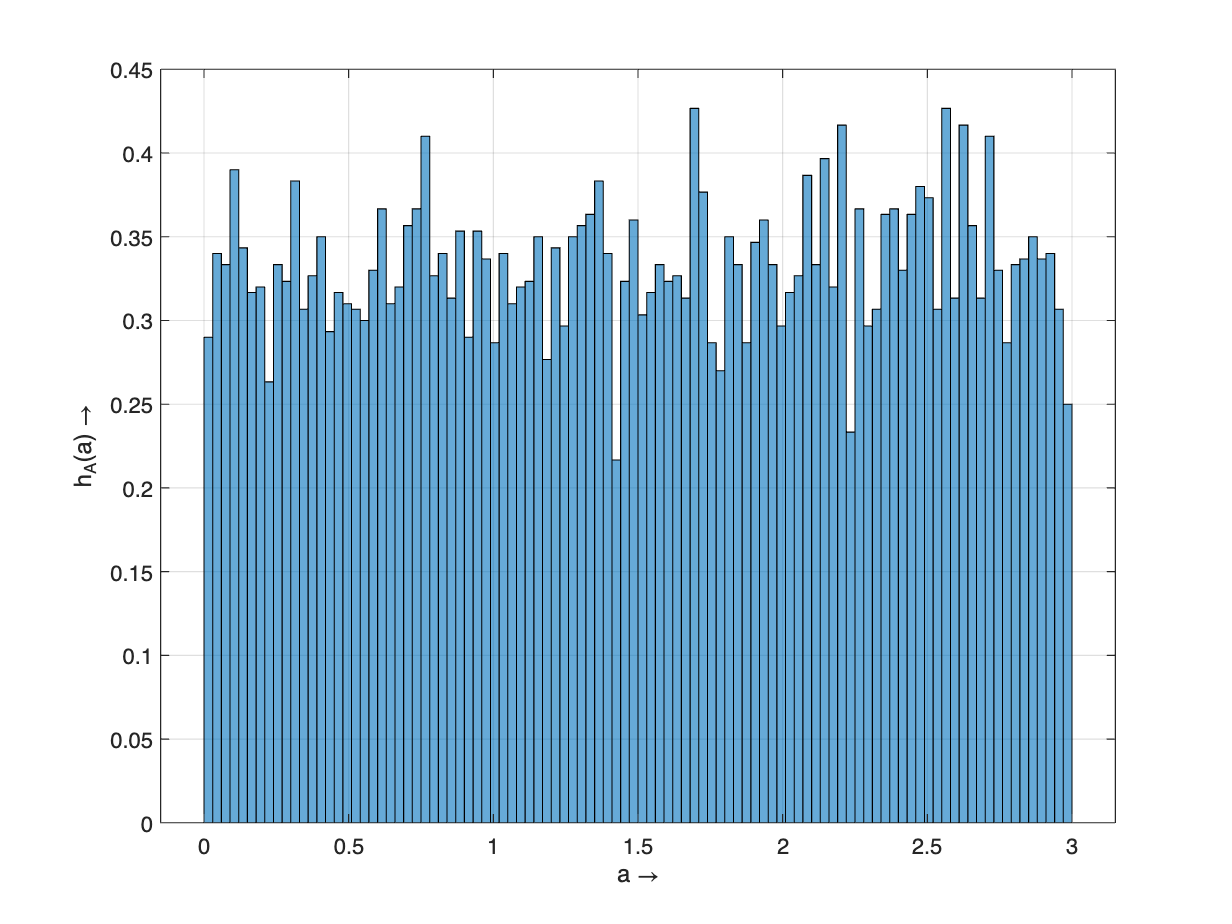

A = A0*rand(1, N);

histogram(A, N/100, 'Normalization', 'pdf'), xlabel('a\rightarrow'), ylabel('h_A(a)\rightarrow'), grid on

#### Aufstellen des Zufallsprozesses

X = A.'*cos(w*t);

#### Berechnung des Mittelwertes

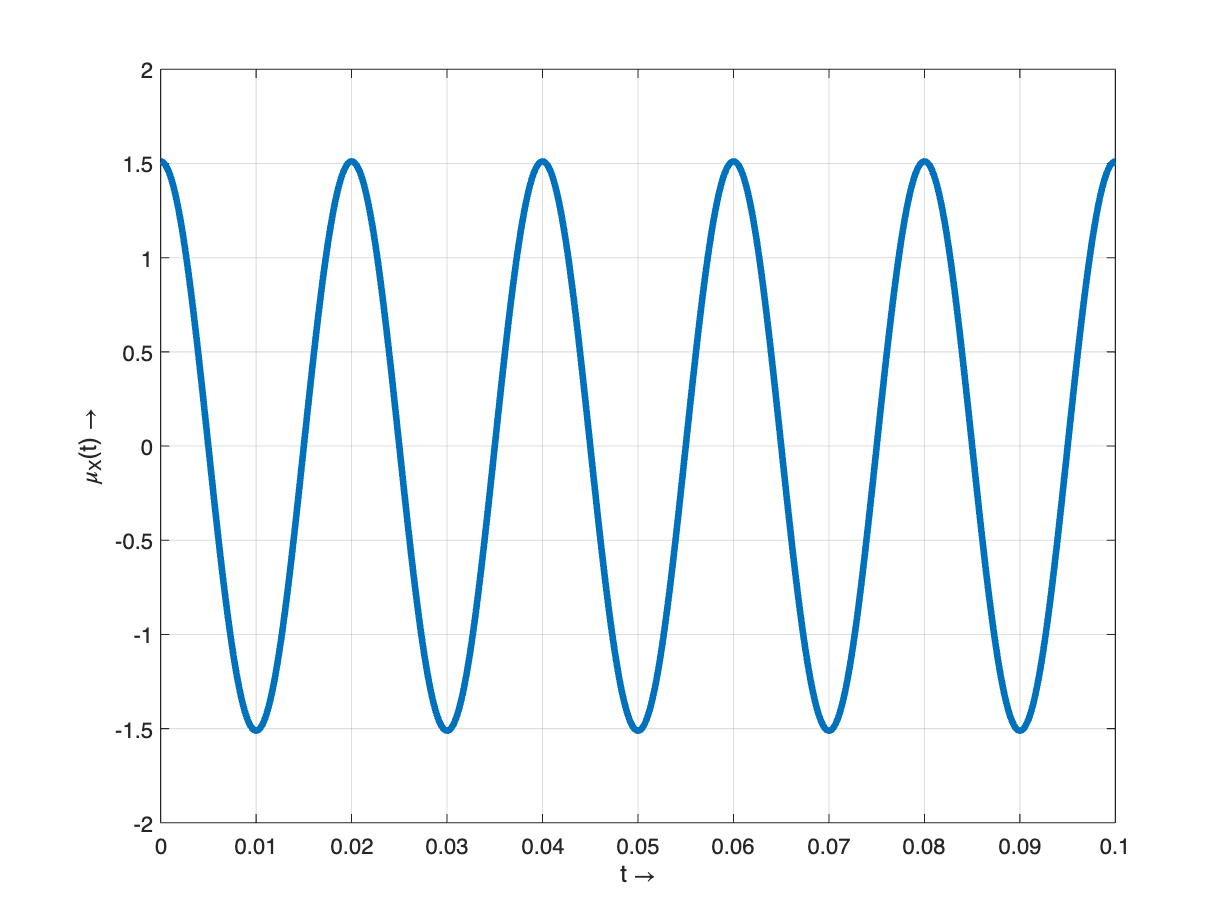

muX = mean(X);
plot(t, muX, LineWidth=3), xlabel('t\rightarrow'), ylabel('\mu_X(t)\rightarrow'), grid on

#### Berechnung der Varianz

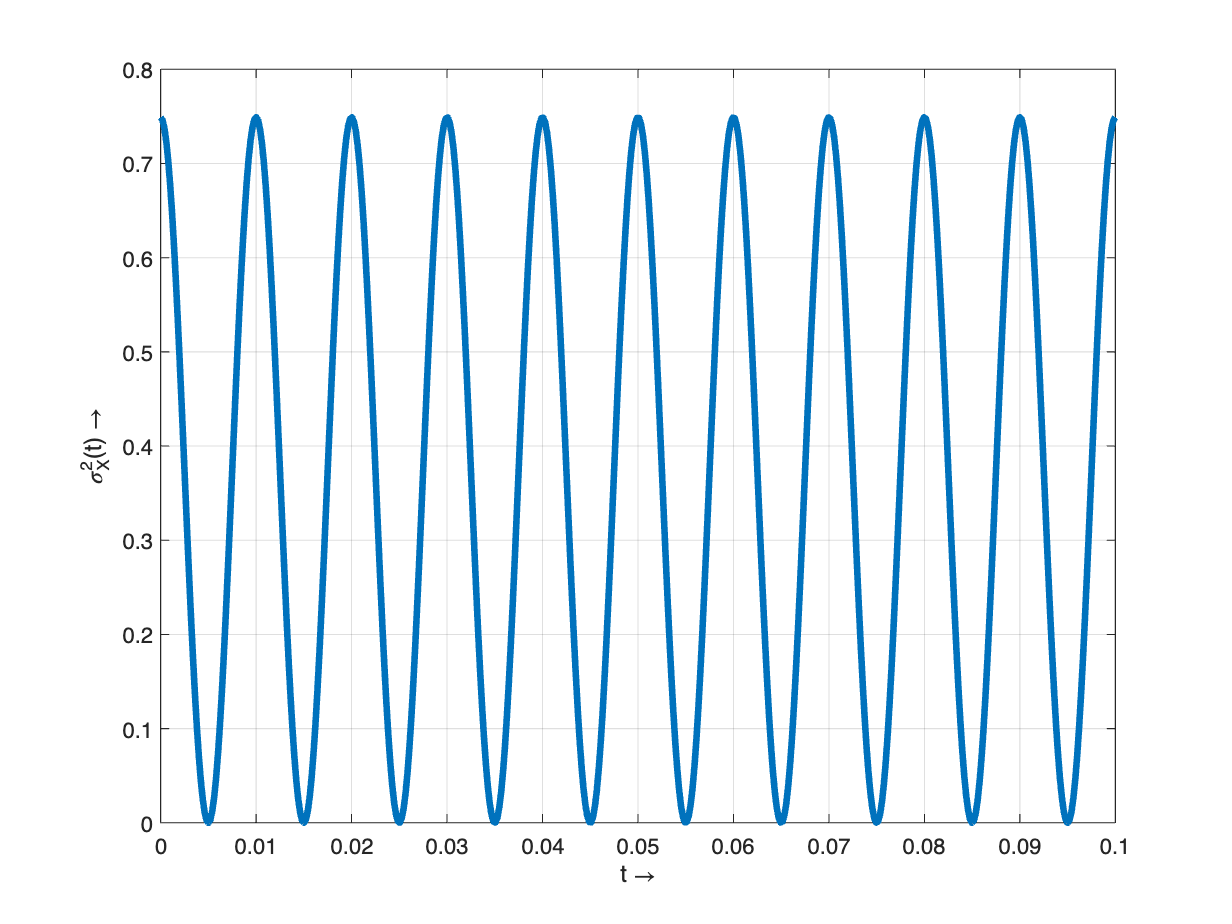

sXs = var(X);
plot(t, sXs, LineWidth=3), xlabel('t\rightarrow'), ylabel('\sigma_X^2(t)\rightarrow'), grid on

#### Berechnen der Autokorrelationsfunktion

phi_XX = zeros(length(t));

for i1 = 1:size(phi_XX, 1)
    for i2 = 1:size(phi_XX, 2)
        phi_XX(i1, i2) = mean(X(:,i1).*X(:,i2));
    end
end

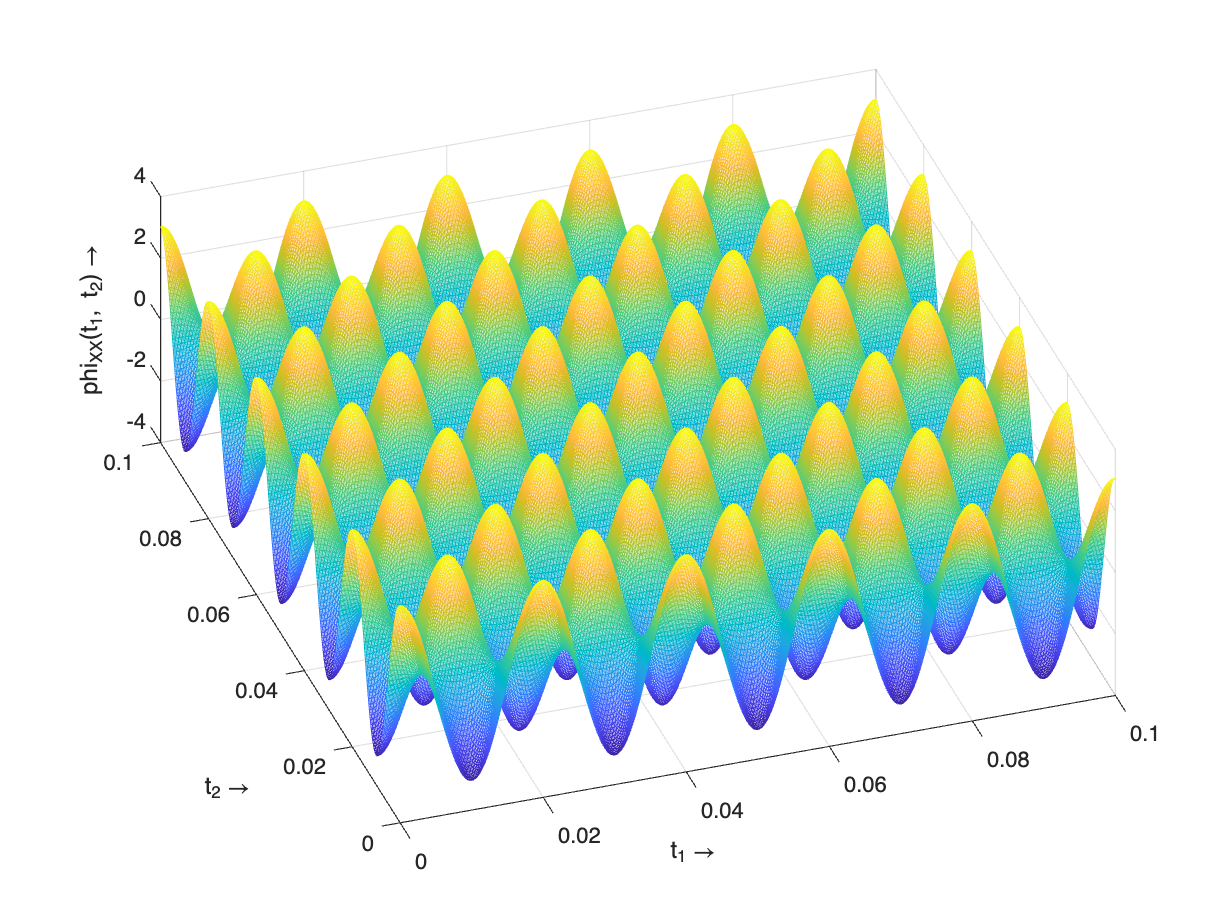

mesh(t, t, phi_XX), xlabel('t_1\rightarrow'), ylabel('t_2\rightarrow'), zlabel('phi_{XX}(t_1, t_2)\rightarrow'), grid on